# 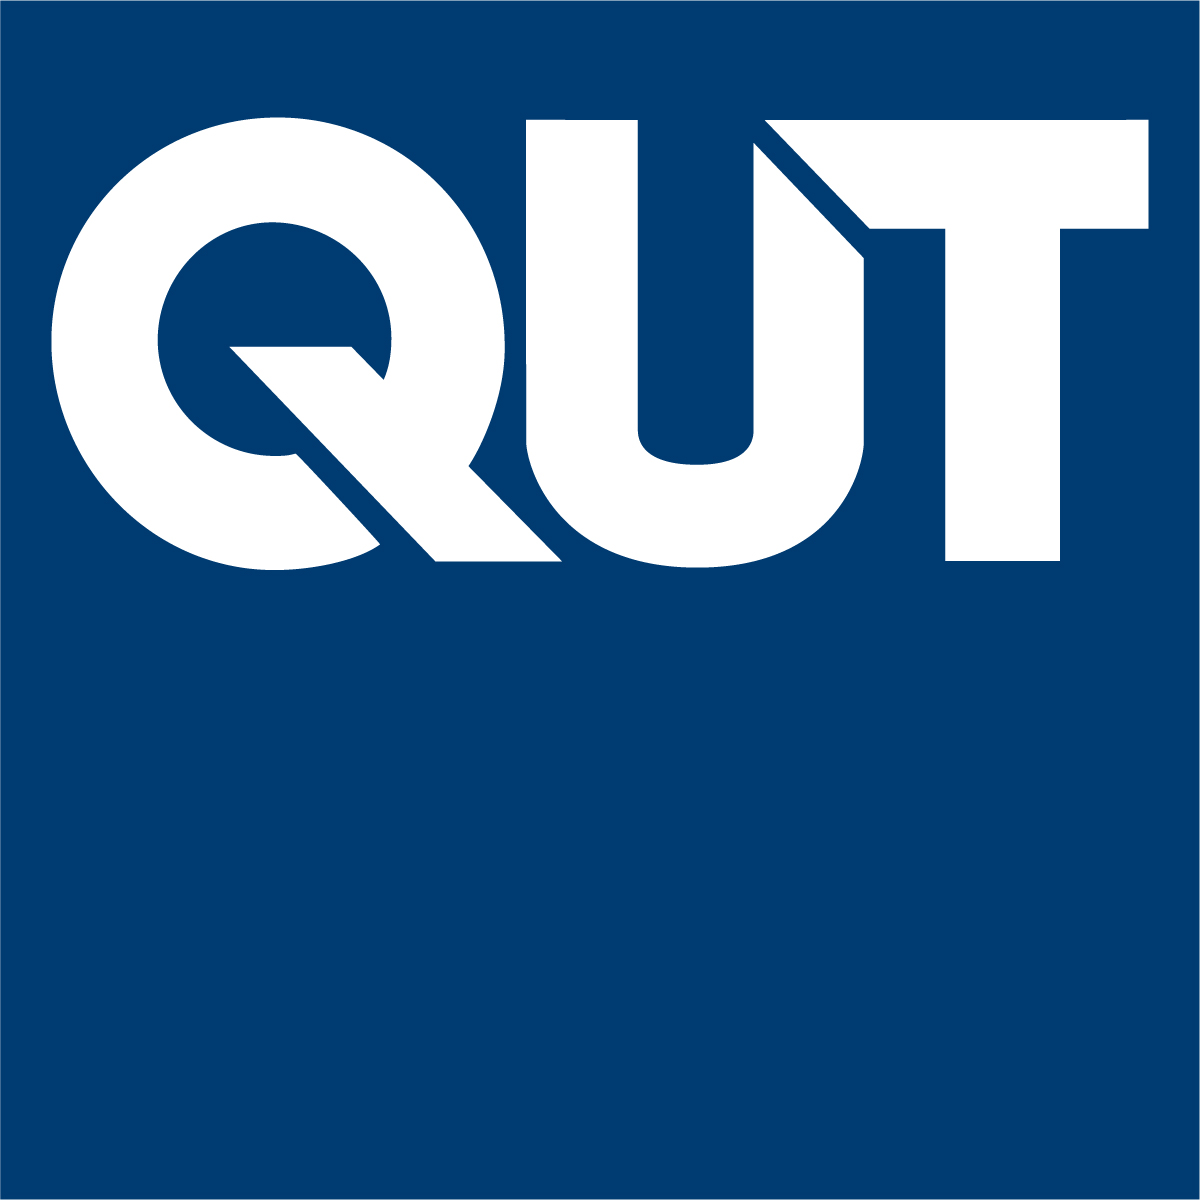

# MXB201 Chapter 6: General Vector and Inner Product spaces

Professor Tim Moroney,  2022

V1.0

## 6.1 Introduction

To this point we have been dealing with real vector spaces, $\mathbb{R}^m$ and $\mathbb{R}^n$, and the transformations between them, or their subspaces, represented by matrices.  We have developed a good set of tools that allow us to analyse and solve many problems in this setting.

In this chapter, we will discover that our tools are much more versatile than we might have realised.  The notion of vector space is not only applicable to $\mathbb{R}^n$ and its subspaces, but much more broadly.  We will learn precisely which characteristics a space must have in order to qualify as a vector space, and identify a number of other familiar spaces that also qualify as vector spaces.  Our tools will thus instantly become applicable to these spaces as well.

Further, we will discover that in fact, all vector spaces of dimension $n$ are equivalent to $\mathbb{R}^n$.  But there are also infinite-dimensional vector spaces, such as spaces of functions, and the tools of linear algebra are applicable to these spaces, too.

## 6.2 Vector Spaces

### Axioms

(Anton 4.1)

The space $\mathbb{R}^n$ has many properties.  However, there are ten properties known as *axioms* that characterise it as a vector space.  All of the linear algebra we have done on this space has relied only on these ten axioms (with the exception of inner products and norms, which are *geometric *constructs -- see Section 6.4).  Hence, we characterise a general vector space as *any* space for which these ten axioms hold.

[Video](https://web.microsoftstream.com/video/38798a22-bd20-4b4d-982a-580f77015a74)

A real vector space $V$ is a set of objects, called vectors, together with the operations of addition (denoted by $+$) and scalar multiplication (denoted by juxtaposition), that satisfy the following ten axioms.

Let $u,v,w \in V$ and $k,m \in \mathbb{R}$ be scalars.  

- $u+v \in V$.

- $u + v = v + u$.

- $u + (v + w) = (u + v) + w$.

- There exists a vector $0 \in V$ such that $u + 0 = 0 + u = u$ for all $u \in V$.

- For all $u \in V$ there is an element $-u \in V$ such that $u + (-u) = 0$.

- $ku \in V$.

- $k(u+v) = ku + kv$.

- $(k+m)u = ku + mu$.

- $k(mu) = (km)u$.

- $1u = u$.

The nature of the operations of vector addition and scalar multiplication are not prescribed by these axioms.  Although we use the familiar notation of $+$ to denote addition, and juxtaposition to denote scalar multiplication, the actual operations need not resemble those of $\mathbb{R}^n$.  All that is required is that the ten axioms are satisfied.

#### Examples of vector spaces

[Video](https://web.microsoftstream.com/video/a91acb98-9200-4461-a522-91814c2dc704)

- The set of column vectors (or row vectors), $\mathbb{R}^n$, with the usual vector addition and scalar multiplication.

- The set of $m \times n$ matrices, $\mathcal{M}_{mn}$, with the usual matrix addition and scalar multiplication.  Note, previously we used $\mathbb{R}^{m \times n}$ to denote $m \times n$ matrices, but for this chapter to ensure we think of the space of matrices as a *bona fide* vector space of its own, we use $\mathcal{M}_{mn}$.

- The set of functions $\mathcal{F}(\Omega)$ that map from some set $\Omega$ to the real numbers, with addition and scalar multiplication defined pointwise.  e.g. $\mathcal{F}(\mathbb{R})$ for functions $f:\mathbb{R} \to \mathbb{R}$, or $\mathcal{F}[a,b]$ for functions $f:[a,b] \to \mathbb{R}$.

Once can show that these examples of vector spaces do indeed satisfy the ten axioms.  (See Anton 4.1, Examples 1--8.)

Any and all further properties of vector spaces follow from these ten axioms.  For example, it can be proved from these axioms (Anton, Theorem 4.1.1) that for any $u \in V$ and any $k \in \mathbb{R}$ that

- 
$$0\,u = 0$$


- 
$$k\,0 = 0$$


- 
$$(-1)\,u = -u$$


- If $k\,u = 0$ then $k = 0$ or $u = 0$.

### Subspaces

(Anton 4.2)

[Video](https://web.microsoftstream.com/video/79721692-b58d-44f9-9210-aadca2246b30)

Suppose we now consider some particular *subset* of $V$, call it $W$: so $W \subset V$.  Is the subset $W$ necessarily also a vector space of its own, with the same notions of addition and scalar multiplication as for $V$?  No.  The subset under consideration needs to satisfy the ten axioms.  It's possible that by excluding elements of $V$, some of the ten axioms will fail to hold for $W$.  For example, consider the vector space $V = \mathbb{R}^2$, and the subset $W$ comprising all vectors of the form $\left[\matrix{x_1 \cr 1}\right]$.  Axiom 1 fails for this subset; it is not closed under vector addition.  For example, $\left[\matrix{2 \cr 1}\right] + \left[\matrix{3 \cr 1}\right] = \left[\matrix{5 \cr 2}\right]$, which fails to have the required form -- vector addition takes us "outside" the subset.

On the other hand, it's still true that $\left[\matrix{2 \cr 1}\right] + \left[\matrix{3 \cr 1}\right] = \left[\matrix{3 \cr 1}\right] + \left[\matrix{2 \cr 1}\right]$, so that Axiom 2 continues to hold.  Careful inspection of the ten axioms reveals that most are in fact automatically satisfied for $W$, since they are "inherited" from the enclosing space $V$.  The four axioms that are not automatically satisfied are :

- Axiom 1: Closure of $W$ under addition.

- Axiom 4: Existence of a zero vector in $W$.

- Axiom 5: Existence of a negative vector in $W$ for every vector in $W$.

- Axiom 6: Closure of $W$ under scalar multiplication.

However, *if *Axioms 1 and 6 can be established, then Axioms 4 and 5 will inherit from the vector space structure of $V$ (Anton Theorem 4.2.1).  So in practice, it suffices to check only Axioms 1 and 6: the subset must be closed under addition and scalar multiplication for it to be a vector space.

A subset of a vector space that is itself a vector space is called a sub**space**.  Hence, any subset $W$ of a vector space which is closed under addition and scalar multiplication is a sub**space.**

#### Examples of subspaces

[Video](https://web.microsoftstream.com/video/9d585ef2-2af0-4c88-a857-d95ffef21c78)

- Lines, planes and higher-dimensional analogues in $\mathbb{R}^n$ *passing through the origin*.

- The set of all symmetric $n \times n$ matrices: matrices $A$ such that $A = A^T$.  We denote this space by $\mathcal{S}_{n} \subset \mathcal{M}_{nn}$.

- The set of all skew symmetric $n \times n$ matrices: matrices $A$ such that $A = -A^T$.  We denote this space by $\mathcal{K}_n \subset \mathcal{M}_{nn}$.

- The set of all polynomials of degree $n$ or less.  We denote this space by $\mathcal{P}_n(\Omega) \subset \mathcal{F}(\Omega)$. e.g. $\mathcal{P}_n(\mathbb{R})$ for polynomials on the real line; $\mathcal{P}_n[a,b]$ for polynomials on the interval $[a,b]$.

- The set of all *continuous* functions $C(\Omega) \subset \mathcal{F}(\Omega)$. e.g. $C(\mathbb{R})$ or $C[a,b]$.

- The set of all functions with continuous *derivatives* on $\Omega$, $C^1(\Omega)$, is a subspace of $C(\Omega)$.  Similarly, we have $C^2(\Omega)$, the set of all functions with continuous second derivatives, which is a subspace of $C^1(\Omega)$, and so on.

- The set of all functions $f$ defined on $[0,1]$ satisfying $f(0) = f(1)$.

**Exercise**

Show that these examples of subspaces are indeed closed under addition and scalar multiplication.  (See also Anton 4.2, Examples 1--10.) ▫

### Terminology and Conventions

[Video](https://web.microsoftstream.com/video/e9f50959-d8d5-4310-a6bf-47d79bf0ba0a)

#### Linear combination, linear independence and span

The notions of of linear combination, linear independence and span are all unchanged for general vector spaces.

Let $c_1, \ldots c_k \in \mathbb{R}$ be scalars.

- A *linear combination* of a set of vectors $S = \{v_1, \ldots v_k\}$ is a vector of the form $v = c_1 v_1 + \ldots + c_k v_k$.

- A set of vectors $S = \{v_1, \ldots v_k\}$ is said to be *linearly independent* if the only solution to $c_1 v_1 + \ldots + c_k v_k = 0$ is the trivial solution $c_1 = \ldots c_k = 0$.  If there are nontrivial solutions, the set is linearly dependent.

- The *span* of a set of vectors $S = \{v_1, \ldots v_k\}$ is the set of *all* linear combinations of that set.  We write $\textrm{span}(S)$ to denote the span of $S$.

#### Basis and dimension

Likewise we carry over the definitions of basis and dimension.

A set of vectors $S = \{v_1, \ldots v_k\}$ is a *basis* for a vector space $V$ if the following conditions hold:

- $S$ is linearly independent.

- $S$ spans $V$,  i.e. $\textrm{span}(S) = V$.

The vector space is said to be of *dimension* $k$ if there are $k$ vectors in its basis.

Not all vector spaces have a basis!  This is a major disruption in moving from $\mathbb{R}^n$ to more general vector spaces.  Important examples of vector spaces with no basis are function spaces, such as $C[a,b]$.  These vector spaces are said to be *infinite-dimensional*.

Examples of *finite*-dimensional vector spaces are $\mathbb{R}^4$, $\mathbb{R}^{2 \times 2}$ and $\mathcal{P}_3$.  The *standard* *bases *for these spaces are:

- 
$$\mathbb{R}^4: S = \left\{\left[\matrix{1 \cr 0 \cr 0 \cr 0}\right], \left[\matrix{0 \cr 1 \cr 0 \cr 0}\right], \left[\matrix{0 \cr 0 \cr 1 \cr 0}\right], \left[\matrix{0 \cr 0 \cr 0 \cr 1}\right]\right\}$$


- 
$$\mathcal{M}_{22}: S = \left\{\left[\matrix{1 & 0 \cr 0 & 0}\right], \left[\matrix{0 & 0 \cr 1 & 0}\right], \left[\matrix{0 & 1 \cr 0 & 0}\right],\left[\matrix{0 & 0 \cr 0 & 1}\right]\right\}$$


- 
$$\mathcal{P}_3: S = \left\{1, x, x^2, x^3\right\}$$


### Examples

#### Example 1

Find a basis for the space $\left\{p \in \mathcal{P}_3[-1,1] | p\prime(-1) = p\prime(1) = 0\right\}$; the space of degree 3 (or less) polynomials satisfying the boundary conditions $p\prime(-1) = 0, p\prime(1) = 0$. What is the dimension of the space?

[Video](https://web.microsoftstream.com/video/d037b1bb-a3fe-4fa2-90a3-7733d6508975)

In MATLAB:

We'll start with the standard basis for $\mathcal{P}_3$, the monomials, and then impose the boundary conditions.

syms x real
n = 3;
Pbasis = x.^(0:n)  % the standard basis

$$Pbasis = \left(\begin{array}{cccc} 1 & x & x^{2} & x^{3} \end{array}\right)$$

Every polynomial in this space can be written as a linear combination of these basis vectors.

c = [sym('c0'); sym('c', [n,1])]  % coordinate vector

$$c = \left(\begin{array}{c} c_{0}\\ c_{1}\\ c_{2}\\ c_{3} \end{array}\right)$$

p = Pbasis * c  % a generic polynomial in P_3

$$p = c_{0}+c_{1}\,x+c_{2}\,x^{2}+c_{3}\,x^{3}$$

Now for the boundary conditions.

eq(1) = subs(diff(p), -1) == 0

$$eq = 3\,c_{3}-2\,c_{2}+c_{1}=0$$

eq(2) = subs(diff(p), 1) == 0

$$eq = \left(\begin{array}{cc} 3\,c_{3}-2\,c_{2}+c_{1}=0 & 3\,c_{3}+2\,c_{2}+c_{1}=0 \end{array}\right)$$

This is a homogeneous system of equations for the coordinates $c_0, c_1, c_2, c_3$, for which the coefficient matrix $A$ is given by

A = equationsToMatrix(eq, c)

$$A = \left(\begin{array}{cccc} 0 & 1 & -2 & 3\\ 0 & 1 & 2 & 3 \end{array}\right)$$

The null space of this matrix is the full set of solutions to the homogeneous linear system.

NS = null(A)

$$NS = \left(\begin{array}{cc} 1 & 0\\ 0 & -3\\ 0 & 0\\ 0 & 1 \end{array}\right)$$

These are the coordinate vectors of the polynomials in our subspace.  We can construct the polynomials themselves using these coordinate vectors.

subspace_basis = Pbasis * NS

$$subspace\_basis = \left(\begin{array}{cc} 1 & -3\,x+x^{3} \end{array}\right)$$

The basis for the space is $\{1, x^3 - 3x\}$.  The dimension of the space is two.

We can easily verify that both basis polynomials satisfy $p\prime(-1) = p\prime(1) = 0$. 

subs(diff(subspace_basis), 1)

$$ans = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

subs(diff(subspace_basis), -1)

$$ans = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

#### Example 2

Find bases for the spaces

- $\mathcal{S}_3$: the space of $3 \times 3$ symmetric matrices

- $\mathcal{K}_3$: the space of $3 \times 3$ skew-symmetric matrices

[Video](https://web.microsoftstream.com/video/6447abcd-059f-4880-9454-c8d48fb9e5a3)

In MATLAB:

We start with a generic matrix $M$ in $\mathcal{M}_{33}$:

n = 3;
M = sym('a', [n n], 'real')

$$M = \left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)$$

To belong to the subspace of symmetric matrices, the 9 entries are not all free to vary.  Only 6 are free, and 3 are fixed by the symmetry.  We'll label the lower triangular entries the same as their upper triangular counterparts to enforce this.

S = subs(M, tril(M), triu(M)')  % Symmetric

$$S = \left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{1,2} & a_{2,2} & a_{2,3}\\ a_{1,3} & a_{2,3} & a_{3,3} \end{array}\right)$$

The six variables we're free to vary are the 1st, 4th, 5th, 7th, 8th and 9th entries in $S$ (counting either by rows or columns).

Sidx = find(triu(S)~=0)

Sidx =      1
     4
     5
     7
     8
     9


These are the variables we can freely vary:

Svars = S(Sidx)

$$Svars = \left(\begin{array}{c} a_{1,1}\\ a_{1,2}\\ a_{2,2}\\ a_{1,3}\\ a_{2,3}\\ a_{3,3} \end{array}\right)$$

Sdim = length(Svars)

Sdim = 6

Similarly, to belong to the subspace of skew-symmetric matrices, only 3 entries are free to vary, and 6 are fixed.  The diagonals must be zero, and the lower triangular entries are the negatives of their upper triangular counterparts.

K = subs(M, tril(M), -triu(M, 1)')  % sKew symmetric

$$K = \left(\begin{array}{ccc} 0 & a_{1,2} & a_{1,3}\\ -a_{1,2} & 0 & a_{2,3}\\ -a_{1,3} & -a_{2,3} & 0 \end{array}\right)$$

The three variables we're free to vary are

Kidx = find(triu(K,1) ~= 0)

Kidx =      4
     7
     8


Kvars = K(Kidx)

$$Kvars = \left(\begin{array}{c} a_{1,2}\\ a_{1,3}\\ a_{2,3} \end{array}\right)$$

Kdim = length(Kvars)

Kdim = 3

Now we extract the bases by sequentially setting all but one of the free variables to zero, and the remaining variable to one.  Here's the basis for the symmetric matrices.

Sbasis = sym(zeros(n,n,Sdim));
I = sym(eye(Sdim));

for j = 1:Sdim
    Sbasis(:,:,j) = subs(S, Svars, I(:,j));  % set all but one variable to 0; the other to 1
end
Sbasis

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 1 & 0\\ 1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 0 & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 1\\ 0 & 1 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Here's the basis for the skew-symmetric matrices.

Kbasis = sym(zeros(n,n,Kdim));
I = sym(eye(Kdim));
for j = 1:Kdim
    Kbasis(:,:,j) = subs(K, Kvars, I(:,j));
end
Kbasis

$$\left(\begin{array}{ccc} 0 & 1 & 0\\ -1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 0 & 0\\ -1 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 1\\ 0 & -1 & 0 \end{array}\right)$$

As we already alluded to, the space $\mathcal{S}_3$ has dimension 6, the space $\mathcal{K}_3$ has dimension 3.

## 6.3 Linear transformations

(Anton Chapter 8)

[Video](https://web.microsoftstream.com/video/40ab6caa-89c7-4b00-b0de-31b072d8e306)

Now that we have a wide variety of vector spaces, it is only natural to consider linear transformations between these spaces.  We are not at all constrained to restrict ourselves to transformations between the same "type" of vector spaces.  For example, we could have a linear transformation from $\mathbb{R}^n$ to $C[-1,1]$, or from $\mathcal{P}_k$ to $\mathcal{M}_{mn}$.

A **linear transformation** $T$ is a mapping from a vector space $V$ to a vector space $W$, satisfying the following two properties for all $u,v \in V$ and all scalars $k \in \mathbb{R}$:

- 
$$T(ku) = kT(u)$$


- 
$$T(u+v) = T(u) + T(v)$$


The defining two properties of a linear transformation mean that we can characterise it completely by considering how the basis vectors from $V$ map to $W$.  Any vector $v \in V$ can be written in terms of a basis $\{v_1, \ldots v_n\}$: $v = c_1  v_1 + \ldots c_n v_n$

So that


$$T(v) = T(c_1  v_1 + \ldots c_n v_n)$$


$T(v) = T(c_1  v_1) + \ldots T(c_n v_n)$  using property (2)

$T(v) = c_1  T(v_1) + \ldots c_n T(v_n)$ using property (1)

Previously we represented linear transformations by matrices.  Now that we are dealing with more general vector spaces, it might seem like that's no longer an option.  But in fact we can still use matrices to represent linear transformations, by using them to describe how the *coordinate vectors* map under the transformation.

Let $(v)_B$ denote the coordinate vector of $v \in V$ relative to the basis $B$ for $V$.

Let $(w)_B\prime$ denote the coordinate vector of $w \in W$ relative to the basis $B\prime$ for $W$.

The matrix representation $A$ of the linear transformation $T$ relative to the two bases $B$ and $B\prime$ is

$A = [T]_{B\prime,B} = \left[(T(v_1))_{B\prime} | (T(v_2))_{B\prime} | \cdots | (T(v_n))_{B\prime}\right]$.

In words: find the transformed basis vectors of $V$, and write them in terms of the basis for $W$.  These coordinate vectors are the columns of the matrix $A$.

You apply this matrix representation of the transformation to the coordinate vector of the input $v$, and you get back the coordinate vector of the output $w$, where $T(v) = w$.  In full:

Let $x = (v)_B$ be the coordinate vector of $v$ relative to the basis $B$ for $V$.

Let $b = (w)_{B\prime}$ be the coordinate vector of $w$ relative to the basis $B\prime$ for $W$.

Then the linear transformation $T(v) = w$ is written in terms of coordinate vectors as $Ax = b$.

Notice how using coordinate vectors brings us right back into our comfort zone of matrices and column vectors.  The particular objects that make up the vector spaces $V$ and $W$ aren't important; only their coordinate vectors matter.

### Kernel and range, rank-nullity theorem

[Video](https://web.microsoftstream.com/video/9ca1b5c3-4216-43fe-934a-c93ea2f95577)

Recall that two of the four fundamental subspaces of a matrix are its null space and its column space.  These two spaces generalise to arbitrary linear transformations, but they get fancy new names: *kernel* and *range*.

Let $T$ be a linear transformation from $V$ to $W$.  The set of all vectors in $V$ that $T$ maps to zero is called the **kernel** of $T$.  The set of all vectors in $W$ that are the images under $T$ of at least one vector in $V$ is called the **range** of $T$.

We retain the terms *rank* and *nullity* for linear transformations that give rise to finite-dimensional range and kernel.

Let $T$ be a linear transformation from $V$ to $W$.  If the range of $T$ is finite-dimensional, its dimension is the **rank** of $T$.  If the kernel of $T$ is finite-dimensional, its dimension is the **nullity** of $T$.

The rank-nullity theorem continues to hold.

Let $T$ be a linear transformation from finite-dimensional vector space $V$ to $W$.  Then

$\textrm{rank}(T) + \textrm{nullity}(T) = \textrm{dim}(V)$.

### Examples

#### Example 3

Let $T:\mathcal{P}_3(\mathbb{R}) \to \mathcal{P}_2(\mathbb{R})$ be the linear transformation defined by $T(p(x)) = p\prime(x)$.

(a) Find the matrix $A$ for $T$ with respect to the standard bases for both spaces.

(b) Find the general solution to $T(p) = x^2 + x + 1$.

[Video](https://web.microsoftstream.com/video/c581948f-bfae-4801-8f99-c853ade049a4)

In MATLAB:

(a) We first define the linear transformation.

T = @(p) diff(p)

T = function_handle with value:
    @(p)diff(p)


Start with the standard basis for the input space, $\mathcal{P}_3$.

Pbasis

$$Pbasis = \left(\begin{array}{cccc} 1 & x & x^{2} & x^{3} \end{array}\right)$$

Apply the linear transformation $T$ to each basis vector:

T_Pbasis = T(Pbasis)

$$T\_Pbasis = \left(\begin{array}{cccc} 0 & 1 & 2\,x & 3\,x^{2} \end{array}\right)$$

Now we need to express these transformed vectors in terms of the basis for the output space $\mathcal{P}_2$.  By inspection we can read off their coordinate vectors.  The code in MATLAB ought to just be something like `A = coeffs(T_Pbasis)`, but for some reason we're not allowed to apply `coeffs` to more than one polynomial at a time, so it's a bit more fiddly.

m = length(Pbasis)-1  % dimension of output space

m = 3

n = length(Pbasis)    % dimension of input space

n = 4

A = sym(zeros(m,n));
for j = 1:n
    coords = flipud(coeffs(T_Pbasis(j), 'all')');
    A(1:length(coords), j) = coords;
end
A

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 2 & 0\\ 0 & 0 & 0 & 3 \end{array}\right)$$

(b) We need the coordinate vector of the right hand side, $x^2 + x + 1$.

b = sym(ones(m,1))

$$b = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

Now we're back to solving good old $Ax = b$!  This is a rectangular system with more columns than rows, so we're on the lookout for probably infinite solutions.

c_nh = A \ b  % here's a particular solution

$$c\_nh = \left(\begin{array}{c} 0\\ 1\\ \frac{1}{2}\\ \frac{1}{3} \end{array}\right)$$

Sure enough, MATLAB warns us that our solution is not unique.  To get the general solution, we need to add the null space component.

NS = null(A)

$$NS = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0 \end{array}\right)$$

So the general solution is

syms C
c_general = c_nh + NS*C  % particular solution plus general null space vector

$$c\_general = \left(\begin{array}{c} C\\ 1\\ \frac{1}{2}\\ \frac{1}{3} \end{array}\right)$$

This is the coordinate vector of the solution.  To complete our answer, we should write the solution in terms of polynomials by finding this particular linear combination of the basis vectors.

Pbasis * c_general

$$ans = C+x+\frac{x^{2}}{2}+\frac{x^{3}}{3}$$

Voila!  We have performed the integration of $x^2 + x + 1$, including the "plus $C$" for full marks.  All that high-school calculus you learned was really just linear algebra all along!

#### Example 4

Let $T: \mathcal{P}_3[-1,1] \to \mathcal{S}_2$ defined by $T(p(x)) = \left[\matrix{p(-1) & p\prime(-1) - p\prime(1) & p\prime\prime(0) \cr
p\prime(-1) - p\prime(1) & p(0) & \int_{-1}^1 p(x)\,\textrm{d}x \cr
p\prime\prime(0) & \int_{-1}^1 p(x)\,\textrm{d}x & p(1) }\right ]$.

(a) Find the matrix $A$ for $T$ with respect to the standard bases for both spaces.

(b) What are the range and kernel of this linear transformation?

(c) Verify the rank-nullity theorem for this linear transformation.

[Video](https://web.microsoftstream.com/video/f362033f-c32c-4d46-bde1-4963956541f6)

In MATLAB:

Define the operator.

T = @(p) [
    subs(p,-1)                        subs(diff(p),-1)-subs(diff(p),1)  subs(diff(p,2), 0)
    subs(diff(p),-1)-subs(diff(p),1)  subs(p,0)                         int(p, [-1,1])
    subs(diff(p,2), 0)                int(p, [-1,1])                    subs(p,1)         ]      

T = function_handle with value:
    @(p)[subs(p,-1),subs(diff(p),-1)-subs(diff(p),1),subs(diff(p,2),0);subs(diff(p),-1)-subs(diff(p),1),subs(p,0),int(p,[-1,1]);subs(diff(p,2),0),int(p,[-1,1]),subs(p,1)]


(a)  Start with the standard basis for the input space, $\mathcal{P}_3$.

n = length(Pbasis)  % dimension of input space

n = 4

Pbasis

$$Pbasis = \left(\begin{array}{cccc} 1 & x & x^{2} & x^{3} \end{array}\right)$$

Apply the linear transformation $T$ to each basis vector:

T_Pbasis = sym(zeros(3,3,n));
for j = 1:n
    T_Pbasis(:,:,j) = T(Pbasis(j));
end
T_Pbasis

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 2\\ 0 & 2 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} 1 & -4 & 2\\ -4 & 0 & \frac{2}{3}\\ 2 & \frac{2}{3} & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Now we need to express these matrices in terms of the basis for the output space $\mathcal{S}_3$.  Again, it's just a little bit fiddly in MATLAB, but what we're doing is nothing special.  Since we're using the standard basis, you could just as easily read off the coordinates by eye.

m = size(Sbasis, 3) % dimension of output space

m = 6

A = sym(zeros(m,n));
for j = 1:n
    T_Pbasis_j = T_Pbasis(:,:,j);
    A(:,j) = T_Pbasis_j(Sidx);
end
A

$$A = \left(\begin{array}{cccc} 1 & -1 & 1 & -1\\ 0 & 0 & -4 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 2 & 0\\ 2 & 0 & \frac{2}{3} & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

(b) Now that we have our transformation matrix, we can find the null space and column space.

NS = null(A), nullityA = size(NS, 2)

$$NS = \left(\begin{array}{c} 0\\ -1\\ 0\\ 1 \end{array}\right)$$

nullityA = 1

CS = colspace(A), rankA = size(CS, 2)

$$CS = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & -\frac{1}{2} & 0\\ 0 & -\frac{1}{6} & 2\\ -1 & -\frac{1}{2} & 2 \end{array}\right)$$

rankA = 3

The fancier-sounding "kernel" and "range" are just these same spaces, expressed in terms of the objects that make up the input and output vector spaces: polynomials in $\mathcal{P}_3$, and $3 \times 3$ symmetric matrices in $\mathcal{S}_3$, respectively.  Let's do the kernel first.

kernel = Pbasis * NS

$$kernel = -x+x^{3}$$

Sure enough, this polynomial does indeed transform to the zero matrix:

T(kernel)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

From its definition, it might not have been obvious that this linear transformation $T$ would have a nonempty kernel.  But sure enough, the polynomial $p(x) = x^3 - x = (x-1)x(x+1)$ has the necessary symmetry to make all of $p(-1) = p(0) = p(1) = p\prime(-1)-p\prime(1) = \int_{-1}^1 p(x)\, \textrm{d}x = 0$.

A basis for the range is found by turning the coordinate vectors in `CS` back into $3 \times 3$ symmetric matrices.  Again, easy to do by eye, and a bit of a pain to do in MATLAB:

range = sym(zeros(3, 3, rankA));
for j = 1:rankA
    range(:,:,j) = subs(S, Svars, CS(:,j));
end
range

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -1 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 1 & -\frac{1}{2}\\ 1 & 0 & -\frac{1}{6}\\ -\frac{1}{2} & -\frac{1}{6} & -\frac{1}{2} \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 1 & 2\\ 0 & 2 & 2 \end{array}\right)$$

The range of $T$ is the span of these three matrices.

(c) The rank-nullity theorem clearly holds for this example.  We have

rankA + nullityA

ans = 4

which is equal to $n$, the dimension of the input space $V$.

n

n = 4

So far our two examples of linear transformations have mapped between different input and output spaces.  When a linear transformation maps from a space onto itself, it is called a *linear operator*.  The eigenvalues and eigenvectors of linear operators can often be of considerable interest in applications.

#### Example 5

Let $T:\mathcal{P}_2([0,1]) \to \mathcal{P}_2([0,1])$ be the linear operator defined by $T(p(x)) = \int_{0}^1 p(t) (x-t)^2\,\textrm{d}t$.

Find the eigenvalues and eigenvectors ("eigenpolynomials"!) of this operator.  That is, find all the polynomials $p_i(x) \in \mathcal{P}_2$ that satisfy $T(p_i(x)) = \lambda_i\, p_i(x)$.

[Video](https://web.microsoftstream.com/video/d57d36e5-b443-4cf3-978d-9acce7ae637e)

In MATLAB:

First define the operator.

syms t
T = @(p) int(subs(p,x,t).*(x-t).^2,t,0,1)

T = function_handle with value:
    @(p)int(subs(p,x,t).*(x-t).^2,t,0,1)


Our goal is to construct the matrix representation $A$ of the operator.  From there, we can find its eigenvalues and eigenvectors.

As usual, start by applying the linear transformation $T$ to each basis vector of the input space.  Here, that's $\mathcal{P}_2[0,1]$.

n = 3 % dimension of vector space

n = 3

Pbasis(1:n)

$$ans = \left(\begin{array}{ccc} 1 & x & x^{2} \end{array}\right)$$

T_Pbasis = T(Pbasis(1:n))

$$T\_Pbasis = \left(\begin{array}{ccc} \frac{1}{3}-x+x^{2} & \frac{1}{4}-\frac{2\,x}{3}+\frac{x^{2}}{2} & \frac{1}{5}-\frac{x}{2}+\frac{x^{2}}{3} \end{array}\right)$$

Now we need to express these transformed vectors in terms of the basis for the output space, which is also $\mathcal{P}_2[0,1]$.  By inspection we can read off their coordinate vectors.  The code in MATLAB ought to just be something like `A = coeffs(T_Pbasis)`, but for some reason we're not allowed to apply `coeffs` to more than one polynomial at a time, so it's a bit more fiddly.

A = sym(zeros(n,n));
for j = 1:n
    coords = flipud(coeffs(T_Pbasis(j), 'all')');
    A(1:length(coords), j) = coords;
end
A

$$A = \left(\begin{array}{ccc} \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ -1 & -\frac{2}{3} & -\frac{1}{2}\\ 1 & \frac{1}{2} & \frac{1}{3} \end{array}\right)$$

In terms of coordinate vectors, we now have an ordinary old eigenvalue problem to solve.

[V,D] = eig(A)

$$V = \left(\begin{array}{ccc} -\frac{1}{2} & \frac{1}{4}-\frac{\sqrt{5}}{20} & \frac{\sqrt{5}}{20}+\frac{1}{4}\\ 1 & -1 & -1\\ 0 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} -\frac{1}{6} & 0 & 0\\ 0 & \frac{1}{12}-\frac{\sqrt{5}}{20} & 0\\ 0 & 0 & \frac{\sqrt{5}}{20}+\frac{1}{12} \end{array}\right)$$

The eigenvalues of the linear operator are:

lambda = diag(D)

$$lambda = \left(\begin{array}{c} -\frac{1}{6}\\ \frac{1}{12}-\frac{\sqrt{5}}{20}\\ \frac{\sqrt{5}}{20}+\frac{1}{12} \end{array}\right)$$

The coordinates of the eigen*polynomials* are found in the columns of $V$.  The eignpolynomials themselves can be constructed using these coordinate vectors.

eigenpolys = Pbasis(1:n) * V

$$eigenpolys = \left(\begin{array}{ccc} -\frac{1}{2}+x & -\frac{\sqrt{5}}{20}+\frac{1}{4}-x+x^{2} & \frac{\sqrt{5}}{20}+\frac{1}{4}-x+x^{2} \end{array}\right)$$

They may not be much to look at, but these are our eigenpolynomials alright.  Let's confirm they each satisfy $T(p_i(x)) = \lambda_i\, p_i(x)$.

T(eigenpolys(1)), lambda(1) * eigenpolys(1)

$$ans = \frac{1}{12}-\frac{x}{6}$$

$$ans = \frac{1}{12}-\frac{x}{6}$$

expand(T(eigenpolys(2))), expand(lambda(2) * eigenpolys(2))

$$ans = \frac{\sqrt{5}\,x}{20}-\frac{x}{12}-\frac{\sqrt{5}}{60}-\frac{\sqrt{5}\,x^{2}}{20}+\frac{x^{2}}{12}+\frac{1}{30}$$

$$ans = \frac{\sqrt{5}\,x}{20}-\frac{x}{12}-\frac{\sqrt{5}}{60}-\frac{\sqrt{5}\,x^{2}}{20}+\frac{x^{2}}{12}+\frac{1}{30}$$

expand(T(eigenpolys(3))), expand(lambda(3) * eigenpolys(3))

$$ans = \frac{\sqrt{5}}{60}-\frac{\sqrt{5}\,x}{20}-\frac{x}{12}+\frac{\sqrt{5}\,x^{2}}{20}+\frac{x^{2}}{12}+\frac{1}{30}$$

$$ans = \frac{\sqrt{5}}{60}-\frac{\sqrt{5}\,x}{20}-\frac{x}{12}+\frac{\sqrt{5}\,x^{2}}{20}+\frac{x^{2}}{12}+\frac{1}{30}$$

### Isomorphism

(Anton 8.3)

[Video](https://web.microsoftstream.com/video/51c3b313-458c-4b15-8e6f-077536ab6b2c)

As is very clear by now, the name of the game with general vector spaces is to pick sensible bases, and convert everything to coordinate vectors.  Then we're back to working with good old matrices and column vectors.  All the tools we acquired in previous chapters are then at our disposal: row reduction, null spaces and column spaces, eigenvalues and eigenvectors, and so on.

There's more to this relationship than just mathematical convenience though.  Look again at the standard bases for $\mathbb{R}^4$, $\mathcal{M}_{22}$  and $\mathcal{P}_3$.

- 
$$\mathbb{R}^4: \left\{\left[\matrix{1 \cr 0 \cr 0 \cr 0}\right], \left[\matrix{0 \cr 1 \cr 0 \cr 0}\right], \left[\matrix{0 \cr 0 \cr 1 \cr 0}\right], \left[\matrix{0 \cr 0 \cr 0 \cr 1}\right]\right\}$$


- 
$$\mathcal{M}_{22}: \left\{\left[\matrix{1 & 0 \cr 0 & 0}\right], \left[\matrix{0 & 0 \cr 1 & 0}\right], \left[\matrix{0 & 1 \cr 0 & 0}\right],\left[\matrix{0 & 0 \cr 0 & 1}\right]\right\}$$


- 
$$\mathcal{P}_3: \left\{1, x, x^2, x^3\right\}$$


When it comes down to it, the *only* differences between these sets of vectors are the notation that we used: either we arranged the ones and zeros into columns, into $2 \times 2$ matrices, or as coefficients of monomials.

Put another way, there is a linear transformation from each of the spaces $\mathbb{R}^4$, $\mathcal{M}_{22}$  and $\mathcal{P}_3$ into each of the others, that maps basis vectors to basis vectors one-to-one by just rewriting them using different notation.

In technical language, a linear transformation $T:V \to W$ that is one-to-one and onto is called an *isomorphism*.  The spaces $V$ and $W$ are said to be *isomorphic* to one another.

A result of fundament importance in linear algebra states that there is in fact **only one real vector space of dimension **$n$.

Theorem: Every real $n$-dimensional vector space is isomorphic to $\mathbb{R}^n$.

Proof: Anton Theorem 8.3.1.

So writing column vectors (or row vectors), or matrices, or polynomials; these are all just notational choices in the end.  The vector space underneath them all is the same.  By simply working with coordinate vectors, we are in effect isomorphically transforming any other $n$-dimensional vector space into $\mathbb{R}^n$, where it is most comfortable to work.

## 6.4 Inner Product Spaces

### Axioms

(Anton 6.1)

[Video](https://web.microsoftstream.com/video/b844d084-638b-48f2-a33e-4701681ffa9b)

The axioms of a vector space, and all that we derived from them, allow us to manipulate vectors algebraically.  But still missing are the *geometric* notions of length and of orthogonality.  For that, we need some additional structure: an **inner product**.

Let $V$ be a vector space.  An *inner product* on $V$ is a function, denoted $\langle\cdot, \cdot\rangle: V \times V \to \mathbb{R}$, that associates a real number with every pair of vectors in $V$, satisfying the following four axioms.

Let $u,v,w \in V$ and $k \in \mathbb{R}$ be a scalar. 

- $\langle u,v \rangle = \langle v,u\rangle$.

- $\langle u+v,w \rangle = \langle u,w\rangle + \langle v,w\rangle$.

- 
$$\langle ku,v\rangle = k\langle u,v\rangle$$


- $\langle u,u\rangle \geq 0$ and $\langle u,u\rangle = 0$ if and only if $u = 0$.

A vector space equipped with an inner product is called an **inner product space**.  Different choices of inner products are possible, and each implies a different notion of length and of orthogonality for that vector space.

Examples of inner products on $\mathbb{R}^n$:

- $\langle u,v\rangle = u \cdot v = u^T v$.  This is the standard inner product we are all very familiar with.  We call it the "dot product".

- $\langle u,v\rangle = u^T A v$ where $A$ is a symmetric positive definite matrix.  This is a *weighted *inner product.  Using this inner product to solve least squares problems leads to *weighted least squares*, which is important in statistics.

[Video](https://web.microsoftstream.com/video/cfa616a7-023e-489b-a025-2d17f44d45ff)

Examples of inner products on $\mathcal{M}_{mn}$ and $\mathcal{P}_n$:

- These spaces are isomorphic to $\mathbb{R}^{mn}$ and $\mathbb{R}^{n+1}$ respectively, so any of the inner products defined above \can be used for these spaces too.

In particular, for $A,B \in \mathcal{M}_{mn}$, the dot product from $\mathbb{R}^{mn}$ translates to $\langle A,B\rangle = \sum_i \sum_j a_{ij}\, b_{ij}$.  There is in fact a purely "matrix" way to write this inner product: it's $\langle A,B\rangle = \textrm{tr}(A^TB)$, where $\textrm{tr}$ is the trace operator (sum of diagonals).

Examples of inner products on $C[a,b]$:

- 
$$\langle f, g\rangle = \int_a^b f(x) g(x)\, \textrm{d}x$$


- $\langle f, g\rangle = \int_a^b f(x) g(x) w(x)\, \textrm{d}x$  where the continuous weight function $w(x)$ is positive for all $x \in [a,b]$.

These inner products are fine to use in $\mathcal{P}_n$ too, and are a better choice in many applications than the "dot product" that $\mathcal{P}_n$ inherits from its isomorphism with $\mathbb{R}^{n+1}$.

### Example 6

Show that the spaces $\mathcal{S}_3$ and $\mathcal{K}_3$ are orthogonal complements in $\mathcal{M}_{33}$ under the standard inner product $\langle A,B\rangle = \textrm{tr}(A^TB)$.

[Video](https://web.microsoftstream.com/video/8940162e-5fa2-47b5-9410-0b9d0ed0080e)

Solution:

We know already that $\dim(\mathcal{S}_3) = 6$ and $\dim(\mathcal{K}_3) = 3$, so the dimensions certainly add to $\dim(\mathcal{M}_{22}) = 9$.  We only need to show that every basis matrix in $\mathcal{S}_3$ is orthogonal to every basis matrix in $\mathcal{K}_3$.  Let's calculate all the pairwise inner products to confirm.

S3dim = size(Sbasis, 3)

S3dim = 6

K3dim = size(Kbasis, 3)

K3dim = 3

IPs = sym(zeros(S3dim, K3dim)); % matrix of inner products
for i = 1:S3dim
    for j = K3dim
        IPs(i,j) = trace(Sbasis(:,:,i)' * Kbasis(:,:,j));
    end
end
IPs

$$IPs = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

All the inner products are zero.  Every matrix in $\mathcal{S}_3$ is orthogonal to every matrix in $\mathcal{K}_3$.

Alternatively, and much more cleanly, we can exploit the isomorphism between $\mathcal{M}_{33}$ and $\mathbb{R}^9$.  We'll reinterpret the $3 \times 3$ basis matrices as 9-dimensional column vectors.

SB = reshape(Sbasis, 9, S3dim)

$$SB = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

KB = reshape(Kbasis, 9, K3dim)

$$KB = \left(\begin{array}{ccc} 0 & 0 & 0\\ -1 & 0 & 0\\ 0 & -1 & 0\\ 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

Now we can just take dot products of the columns.

SB' * KB

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Since the spaces are orthogonal complements, any matrix $A \in \mathcal{M}_{33}$ can be written as the sum of its orthogonal projection onto $\mathcal{S}_3$ and its orthogonal projection onto $\mathcal{K}_3$.  What do these projections look like for an arbitrary matrix?  Let's build the projectors and find out!

P_S = SB*inv(SB'*SB)*SB'  % orthogonal projector onto subspace S_3

$$P\_S = \left(\begin{array}{ccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{2} & 0 & \frac{1}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{2} & 0 & 0 & 0 & \frac{1}{2} & 0 & 0\\ 0 & \frac{1}{2} & 0 & \frac{1}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{2} & 0 & \frac{1}{2} & 0\\ 0 & 0 & \frac{1}{2} & 0 & 0 & 0 & \frac{1}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{2} & 0 & \frac{1}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

P_K = KB*inv(KB'*KB)*KB'  % orthogonal projector onto subspace K_3

$$P\_K = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{2} & 0 & -\frac{1}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{2} & 0 & 0 & 0 & -\frac{1}{2} & 0 & 0\\ 0 & -\frac{1}{2} & 0 & \frac{1}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{2} & 0 & -\frac{1}{2} & 0\\ 0 & 0 & -\frac{1}{2} & 0 & 0 & 0 & \frac{1}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{1}{2} & 0 & \frac{1}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Now we can project our general matrix $M \in \mathcal{M}_{33}$ onto each space and see what we get.

M

$$M = \left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)$$

First onto $\mathcal{S}_3$:

P_S * M(:)  % as a vector in R^9

$$ans = \left(\begin{array}{c} a_{1,1}\\ \frac{a_{1,2}}{2}+\frac{a_{2,1}}{2}\\ \frac{a_{1,3}}{2}+\frac{a_{3,1}}{2}\\ \frac{a_{1,2}}{2}+\frac{a_{2,1}}{2}\\ a_{2,2}\\ \frac{a_{2,3}}{2}+\frac{a_{3,2}}{2}\\ \frac{a_{1,3}}{2}+\frac{a_{3,1}}{2}\\ \frac{a_{2,3}}{2}+\frac{a_{3,2}}{2}\\ a_{3,3} \end{array}\right)$$

symmetric_part = reshape(ans, size(M)) % as a matrix in M_33

$$symmetric\_part = \left(\begin{array}{ccc} a_{1,1} & \frac{a_{1,2}}{2}+\frac{a_{2,1}}{2} & \frac{a_{1,3}}{2}+\frac{a_{3,1}}{2}\\ \frac{a_{1,2}}{2}+\frac{a_{2,1}}{2} & a_{2,2} & \frac{a_{2,3}}{2}+\frac{a_{3,2}}{2}\\ \frac{a_{1,3}}{2}+\frac{a_{3,1}}{2} & \frac{a_{2,3}}{2}+\frac{a_{3,2}}{2} & a_{3,3} \end{array}\right)$$

Unsurprisingly perhaps, the symmetric part is just $(M+M^T)/2$.

Now onto $\mathcal{K}_3$:

P_K * M(:)  % as a vector in R^9

$$ans = \left(\begin{array}{c} 0\\ \frac{a_{2,1}}{2}-\frac{a_{1,2}}{2}\\ \frac{a_{3,1}}{2}-\frac{a_{1,3}}{2}\\ \frac{a_{1,2}}{2}-\frac{a_{2,1}}{2}\\ 0\\ \frac{a_{3,2}}{2}-\frac{a_{2,3}}{2}\\ \frac{a_{1,3}}{2}-\frac{a_{3,1}}{2}\\ \frac{a_{2,3}}{2}-\frac{a_{3,2}}{2}\\ 0 \end{array}\right)$$

skew_symmetric_part = reshape(ans, size(M)) % as a matrix in M_33

$$skew\_symmetric\_part = \left(\begin{array}{ccc} 0 & \frac{a_{1,2}}{2}-\frac{a_{2,1}}{2} & \frac{a_{1,3}}{2}-\frac{a_{3,1}}{2}\\ \frac{a_{2,1}}{2}-\frac{a_{1,2}}{2} & 0 & \frac{a_{2,3}}{2}-\frac{a_{3,2}}{2}\\ \frac{a_{3,1}}{2}-\frac{a_{1,3}}{2} & \frac{a_{3,2}}{2}-\frac{a_{2,3}}{2} & 0 \end{array}\right)$$

The skew-symmetric part is just $(M-M^T)/2$.

Every square matrix $A$ can be decomposed into the sum of its symmetric part $S = (M+M^T)/2$ and its skew symmetric part $K = (M - M^T)/2$.  Furthermore, $\langle S, K \rangle = 0$ under the trace inner product, so that this is an orthogonal decomposition.

### Norms

[Video](https://web.microsoftstream.com/video/d8b908c8-3888-4741-a14b-a1feac29a1ca)

Having defined an inner product, we also get a natural way to measure of the length of a vector: its norm $\|u\|$, defined by

$\|u\| = \sqrt{\langle u,u\rangle}$.

The norm defined this way inherits from the inner product all the properties we would expect it to have:

- $\|u\| \geq 0$ and $\|u\| = 0$ if and only if $u = 0$.

- $\|ku\| = |k|\|u\|$ for scalar $k$.

- $\|u + v\| \leq \|u\| + \|v\|$.  *The triangle inequality.*

**Example: **$\mathcal{M}_{mn}$

For $\mathcal{M}_{mn}$, the inner product inherited from $\mathbb{R}^{mn}$ leads to the norm of a matrix being defined by $\|A\| = \sqrt{\langle A, A\rangle} = \sqrt{\textrm{tr}(A^T A)} = \sqrt{\sum_i \sum_j a_{ij}^2$ .  This is known as the *Frobenius norm*.  It is not, however, the default matrix norm in MATLAB.  In MATLAB, if you type `norm(A)` you get a different norm (which we won't cover in this unit).  To request the Frobenius norm, it's `norm(A, 'fro')`.

Using the terminology of norms, we can say from our previous example that the nearest symmetric matrix $S$ to any matrix $M \in \mathcal{M}_{nn}$, as measured by the Frobenius norm $\|M - S\|$, is its symmetric part $S = (M+M^T)/2$.  Similarly, the nearest skew-symmetric matrix $K$, as measured by the Frobenius norm $\|M - K\|$, is $K = (M - M^T)/2$.

### Orthogonality and the Gram-Schmidt process

(Anton 6.2--6.3)

[Video](https://web.microsoftstream.com/video/f964d732-1004-464e-93fc-c8fa933d5526)

Besides inducing a norm, the other main use of an inner product is to define the notion of *orthogonality*.  Two vectors $u,v$ are orthogonal, with respect to the chosen inner product $\langle \cdot, \cdot \rangle$, if $\langle u,v\rangle = 0$.

A set $Q = \{q_1, q_2, \ldots q_k\}$ is called an *orthonormal basis* for the vector space $\textrm{span}(Q)$ if $\langle q_i, q_j \rangle = \delta_{ij}$ (Kronecker delta).  (We won't give a particular name to the vector space for which $Q$ is a basis, since all the obvious choices for variable names have other duties below -- so the space is simply $\textrm{span}(Q)$.)

Orthonormal bases for general inner product spaces provide all the advantages we're used to from $\mathbb{R}^n$.  In particular, we have the following immensely useful result for finding orthogonal projections:

Let a $k$-dimensional subspace of an inner product space $V$ have orthonormal basis $Q = \{q_1, q_2, \ldots q_k\}$.  The orthogonal projection of $u \in V$ onto $\textrm{span}(Q)$ is given by


$$\textrm{Proj}_{\textrm{span}(Q)}(u) = \langle u, q_1\rangle q_1 + \langle u, q_2\rangle q_2 + \ldots + \langle u, q_k\rangle q_k.$$


This is true even if $V$ is infinite dimensional.

Like all orthogonal projections, the vector $\textrm{Proj}_{\textrm{span}(Q)}(u)$ satisfies

$\textrm{Proj}_{\textrm{span}(Q)}(u) = \textrm{argmin}_{u^* \in \textrm{span}(Q)} \|u - u^*\|$,

meaning it is the *least squares solution* to the problem of finding the closest vector in $\textrm{span}(Q)$ to $u$.

The *Gram-Schmidt process* generalises to general inner product spaces exactly as you would expect.  You start with a non-orthonormal basis for your space.  Then, one basis vector at a time, you subtract off its projections onto the previously calculated orthonormal basis vectors, before finally normalising, to obtain the next orthonormal basis vector.

The Gram-Schmidt process for a general inner product space:

Input: a set $W = \{w_1, w_2, \ldots w_k\} \subset V$ of linearly independent vectors.

Output: a set $Q = \{q_1, q_2, \ldots q_k\}$ which is an orthonormal basis for $\textrm{span}(W)$, i.e. $\textrm{span}(Q) = \textrm{span}(W)$.


$$v_1 = w_1 ; \qquad \qquad \qquad \qquad\qquad \qquad \qquad \qquad  \quad \ \,  q_1 = v_1 / \|v_1\|$$



$$v_2 = w_2 - \langle w_2 , q_1\rangle \,q_1; \qquad\qquad \qquad \qquad \qquad  \qquad\ \, q_2 = v_2 / \|v_2\|$$



$$v_3 = w_3 - \langle w_3, q_1\rangle \,q_1 - \langle w_3 , q_2\rangle \,q_2; \qquad \qquad \qquad \quad \ q_3 = v_3 / \|v_3\|$$



$$v_4 = w_4 - \langle w_4, q_1\rangle \,q_1 - \langle w_4, q_2\rangle \,q_2 - \langle w_4 ,q_3\rangle \,q_3; \quad\ \ \ q_4 = v_4 / \|v_4\|$$


and in general,


$$v_i = w_i - \sum_{j = 1}^{i-1} \langle w_i , q_j\rangle \,q_j; \qquad \qquad 
 \qquad \qquad \qquad \quad \ 
q_i = v_i / \|v_i\|$$
   

### Examples

#### Example 7

Use the Gram-Schmidt process to find an orthonormal basis for $\mathcal{P}_3[-1,1]$ under the inner product $\langle p,q\rangle = \int_{-1}^1 p(x) q(x)\,\textrm{d}x$.

[Video](https://web.microsoftstream.com/video/2663e9af-4de0-4f17-ab69-26869d7b4c08)

Solution:

We first define functions for the inner product, and associated norm.

ip = @(f,g) int(f.*g, [-1,1]), nrm = @(f) sqrt(ip(f,f))

ip = function_handle with value:
    @(f,g)int(f.*g,[-1,1])


nrm = function_handle with value:
    @(f)sqrt(ip(f,f))


We start with the standard basis for $\mathcal{P}_3[-1,1]$:

W = Pbasis

$$W = \left(\begin{array}{cccc} 1 & x & x^{2} & x^{3} \end{array}\right)$$

The first orthonormal basis vector $q_1$ is just the first vector $w_1$, normalised:

Q = sym('q', size(W))

$$Q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

Q(1) = W(1) / nrm(W(1))

$$Q = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

For the second orthonormal basis vector $q_2$, we start with $w_2$ and subtract off its projection onto $q_1$:

Q(2) = W(2) - Q(1) * ip(W(2), Q(1)); % subtract off projection

Then normalise:

Q(2) = Q(2) / nrm(Q(2))              % normalise

$$Q = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & q_{3} & q_{4} \end{array}\right)$$

Repeat the process for the remaining vectors; starting with $w_j$, then subtracting off its projections onto $q_1, \ldots q_{j-1}$:

Q(3) = W(3) - Q(1:2) * ip(W(3), Q(1:2))'; % subtract off projections

before normalising:

Q(3) = Q(3) / nrm(Q(3))                   % normalise

$$Q = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,\left(-\frac{1}{3}+x^{2}\right)}{4} & q_{4} \end{array}\right)$$

Q(4) = W(4) - Q(1:3) * ip(W(4), Q(1:3))'; % subtract off projections
Q(4) = Q(4) / nrm(Q(4))                   % normalise

$$Q = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,\left(-\frac{1}{3}+x^{2}\right)}{4} & \frac{5\,\sqrt{2}\,\sqrt{7}\,\left(-\frac{\sqrt{2}\,\sqrt{3}\,\sqrt{6}\,x}{10}+x^{3}\right)}{4} \end{array}\right)$$

The resulting orthonormal polynomials on $[-1,1]$ are the famous *Legendre* polynomials.  Although, usually for aesthetic purposes they are normalised not to have unit length (as we require), but to take the value 1 at $x = 1$.

Legendre = simplify(Q ./ subs(Q,1))

$$Legendre = \left(\begin{array}{cccc} 1 & x & -\frac{1}{2}+\frac{3\,x^{2}}{2} & \frac{x\,\left(-3+5\,x^{2}\right)}{2} \end{array}\right)$$

Here's what these first four Legendre polynomials look like.

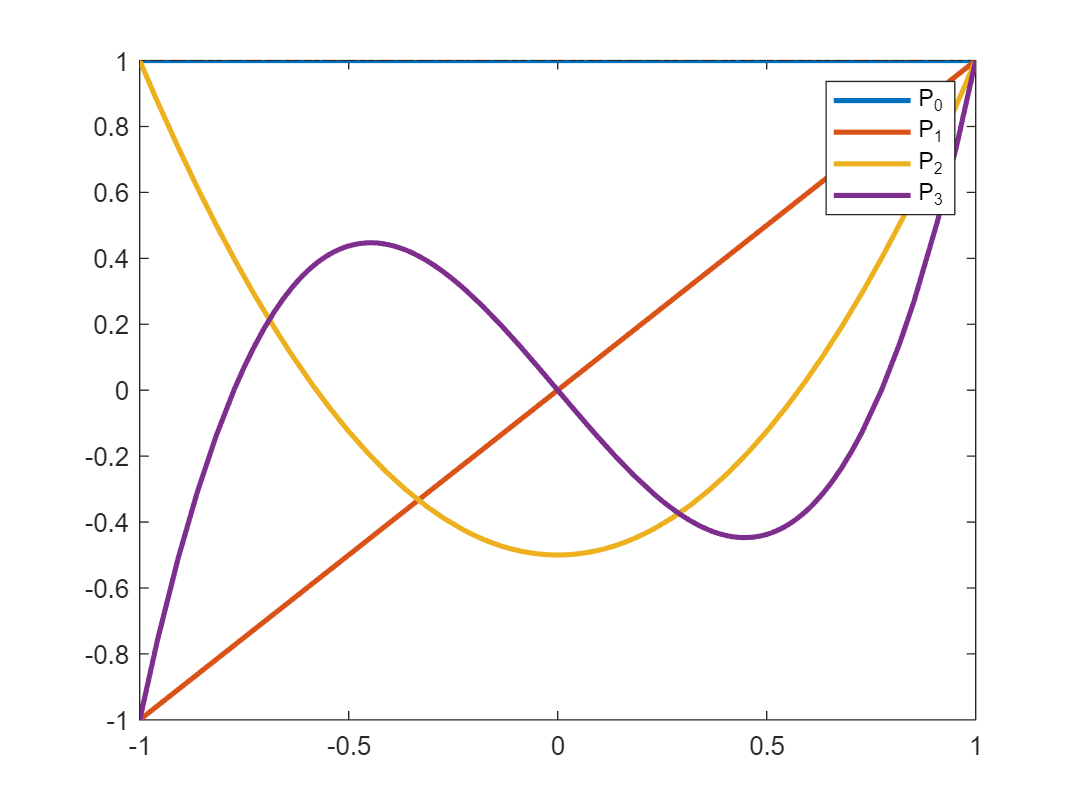

figure, fplot(Legendre, [-1,1], 'LineWidth', 2)
legend([repmat('P_',4,1) num2str((0:3)')])

The power of orthogonal projections becomes apparent when we consider this space $\mathcal{P}_3[-1,1]$ as a subspace of $C[-1,1]$.  We can project *any continuous function we like* onto this space, and hence find its least squares approximation in $\mathcal{P}_3[-1,1]$.  That is, we can, with remarkable ease, find the polynomial $p$ of degree 3 that best approximates any continuous function $f$ in the sense of minimising the "mean square error":


$$\|f - p\|^2 = \int_{-1}^1 (f(x) - p(x))^2\, \textrm{d}x\,.$$


It's as simple as finding the coordinate vector of $f$, or rather of its orthogonal projection, with respect to the orthonormal basis for $\mathcal{P}_3$.

#### Example 8

Find the optimal approximation of $f(x) = e^x$ by a polynomial of degree 3 on $[-1,1]$, in the least squares sense.

[Video](https://web.microsoftstream.com/video/17fef820-e5ba-4a48-8b39-74e9f1f3efa9)

Solution:

We define our function $f$.

f = exp(x)

$$f = {\mathrm{e}}^{x}$$

Then we calculate its coordinate vector $c$ with respect to the orthonormal basis for $\mathcal{P}[-1,1]$: $c_j = \langle f,q_j\rangle$.

Because $f$ is not actually a member of $\mathcal{P}_3[-1,1]$, we are really calculating the coordinate vector of its orthogonal projection onto $\mathcal{P}_3[-1,1]$.

Cproj_f = ip(f, Q)'

$$Cproj\_f = \left(\begin{array}{c} \frac{\sqrt{2}\,{\mathrm{e}}^{-1}\,\left({\mathrm{e}}^{2}-1\right)}{2}\\ \sqrt{6}\,{\mathrm{e}}^{-1}\\ \frac{\sqrt{10}\,{\mathrm{e}}^{-1}\,\left({\mathrm{e}}^{2}-7\right)}{2}\\ -\frac{\sqrt{14}\,{\mathrm{e}}^{-1}\,\left(5\,{\mathrm{e}}^{2}-37\right)}{2} \end{array}\right)$$

The projection itself is then found by taking this linear combination of the basis polynomials.

proj_f = Q * Cproj_f

$$proj\_f = \frac{{\mathrm{e}}^{-1}\,\left({\mathrm{e}}^{2}-1\right)}{2}+\frac{\sqrt{2}\,\sqrt{3}\,\sqrt{6}\,x\,{\mathrm{e}}^{-1}}{2}-\frac{5\,\sqrt{2}\,\sqrt{7}\,\sqrt{14}\,{\mathrm{e}}^{-1}\,\left(5\,{\mathrm{e}}^{2}-37\right)\,\left(-\frac{\sqrt{2}\,\sqrt{3}\,\sqrt{6}\,x}{10}+x^{3}\right)}{8}+\frac{3\,\sqrt{2}\,\sqrt{5}\,\sqrt{10}\,{\mathrm{e}}^{-1}\,\left(-\frac{1}{3}+x^{2}\right)\,\left({\mathrm{e}}^{2}-7\right)}{8}$$

Just like that, we have our orthogonal projection!  Let's take a look at it in action.  Here it is plotted by comparision with $f$.

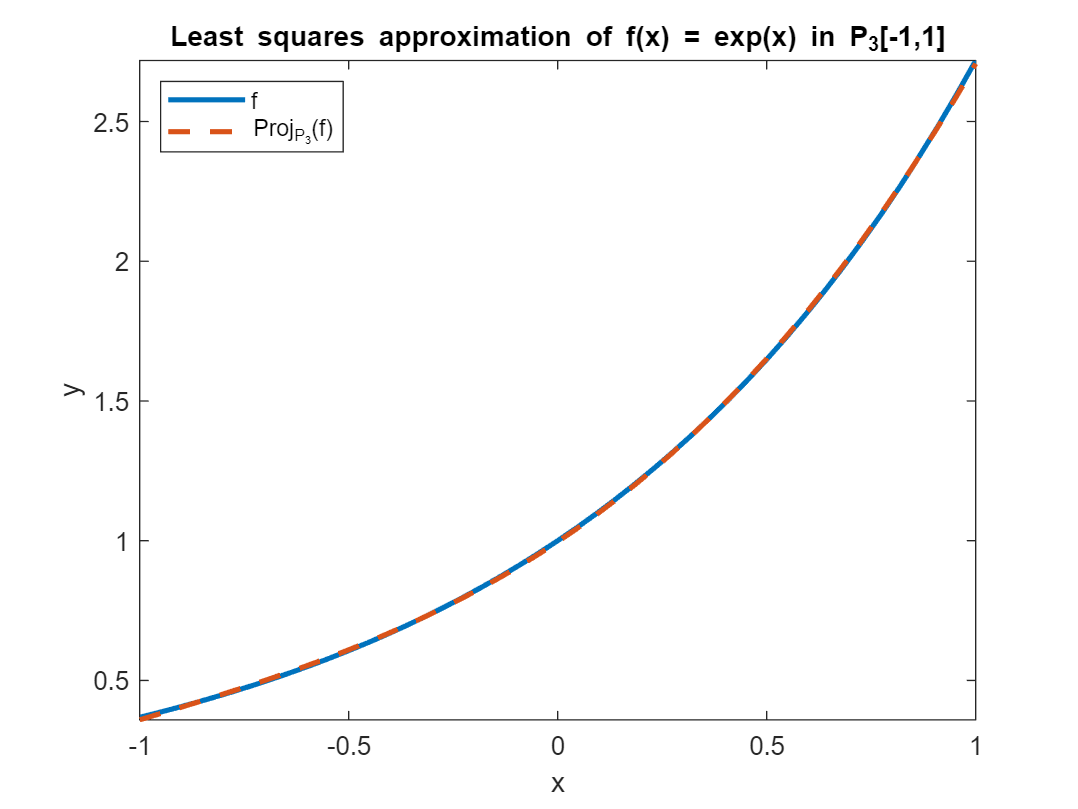

figure
fplot(f, [-1,1], 'DisplayName','f', 'LineWidth', 2)
hold on
fplot(proj_f, [-1,1], '--', 'DisplayName','Proj_{P_3}(f)', 'LineWidth', 2)
legend('location', 'northwest')
xlabel('x'), ylabel('y')
title(sprintf('Least squares approximation of f(x) = %s in P_3[-1,1]', char(f)))

To a couple of decimal places, our least squares polynomial is

vpa(proj_f, 6)

$$ans = 0.996294+0.997955\,x+0.536722\,x^{2}+0.176139\,x^{3}$$

The coefficients might remind you of another familiar polynomial, the Taylor polynomial of degree 3 for $e^x$:

taylor = series(f, x, 0, 'order', 4)

$$taylor = 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}$$

The coefficients are similar, but our least squares polynomial gives a much smaller mean square error than the Taylor polynomial.

double(nrm(f - proj_f))  % this is the square root of the mean square error

ans = 0.0047

double(nrm(f - taylor))  % this is the square root of the mean square error

ans = 0.0205

The least squares polynomial, by its construction, gives the smallest mean square error you can possibly get on the interval $[-1,1]$ with a polynomial of degree 3.  The Taylor polynomial focuses all its attention on $x = 0$, and so it drifts too far away from $f$ to be competitive over the whole interval $[-1,1]$.

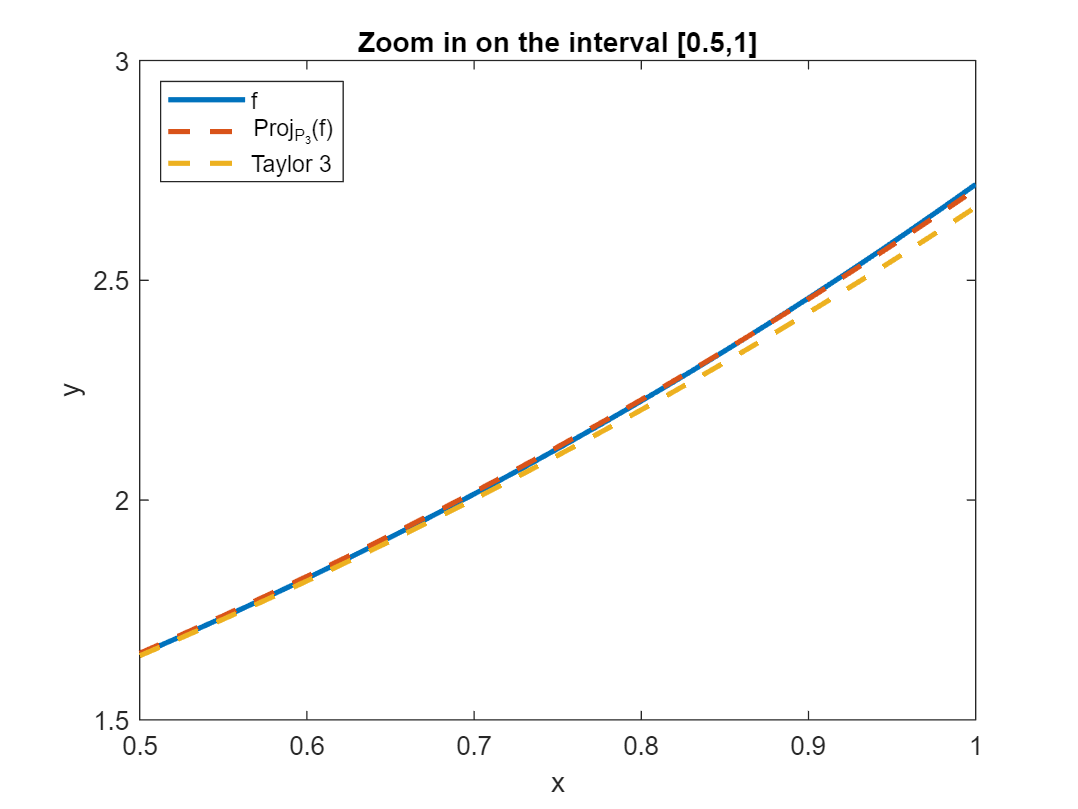

fplot(taylor, [-1,1], '--', 'DisplayName','Taylor 3', 'LineWidth', 2)
axis([0.5,1,1.5,3])
title('Zoom in on the interval [0.5,1]')

#### Example 9

(a) Find an orthonormal basis for the subspace of $C[0,2\pi]$ spanned by $\{1, \cos(x), \cos(2x), \sin(x), \sin(2x)\}$.

(b) Hence find the trigonometric polynomial $p_n(x) = a_0 + a_1\cos(x) + a_2\cos(2x) + b_1\sin(x) + b_2\sin(2x)$ that best approximates the function $f(x) = x$ in the least squares sense.

[Video](https://web.microsoftstream.com/video/318fc8d3-2707-4402-aa57-6d5072313f62)

Solution:

(a)  We first define functions for the inner product, and associated norm

ip = @(f,g) int(f.*g, [0,2*pi]), nrm = @(f) sqrt(ip(f,f))

ip = function_handle with value:
    @(f,g)int(f.*g,[0,2*pi])


nrm = function_handle with value:
    @(f)sqrt(ip(f,f))


The input basis is $W = \{1, \cos(x), \cos(2x), \sin(x), \sin(2x)\}$.

n = 2

n = 2

W = [cos((0:n).*x) sin((1:n).*x)]

$$W = \left(\begin{array}{ccccc} 1 & \cos\left(x\right) & \cos\left(2\,x\right) & \sin\left(x\right) & \sin\left(2\,x\right) \end{array}\right)$$

In fact, this basis is *already* *orthogonal* over $[0,2\pi]$!

ip(W', W)

$$ans = \left(\begin{array}{ccccc} 2\,\pi & 0 & 0 & 0 & 0\\ 0 & \pi & 0 & 0 & 0\\ 0 & 0 & \pi & 0 & 0\\ 0 & 0 & 0 & \pi & 0\\ 0 & 0 & 0 & 0 & \pi \end{array}\right)$$

The Gram-Schmidt process is unnecessary.  All we need to do is divide each function by its norm.

Q = W ./ nrm(W)

$$Q = \left(\begin{array}{ccccc} \frac{\sqrt{2}}{2\,\sqrt{\pi }} & \frac{\cos\left(x\right)}{\sqrt{\pi }} & \frac{\cos\left(2\,x\right)}{\sqrt{\pi }} & \frac{\sin\left(x\right)}{\sqrt{\pi }} & \frac{\sin\left(2\,x\right)}{\sqrt{\pi }} \end{array}\right)$$

This is now an orthonormal basis, as we can easily confirm.

ip(Q', Q)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

(b) Now define the function $f$.

f = x

$$f = x$$

We calculate its projection onto the space by finding its coordinate vector $c_j = \langle f, q_j\rangle$.

c_Proj_f = ip(f, Q)'

$$c\_Proj\_f = \left(\begin{array}{c} \sqrt{2}\,\pi^{3/2}\\ 0\\ 0\\ -2\,\sqrt{\pi }\\ -\sqrt{\pi } \end{array}\right)$$

Then take this linear combination of the basis vectors to get the required trigonometric polynomial.

Proj_f = Q * c_Proj_f

$$Proj\_f = \pi -\sin\left(2\,x\right)-2\,\sin\left(x\right)$$

Here it is in action.

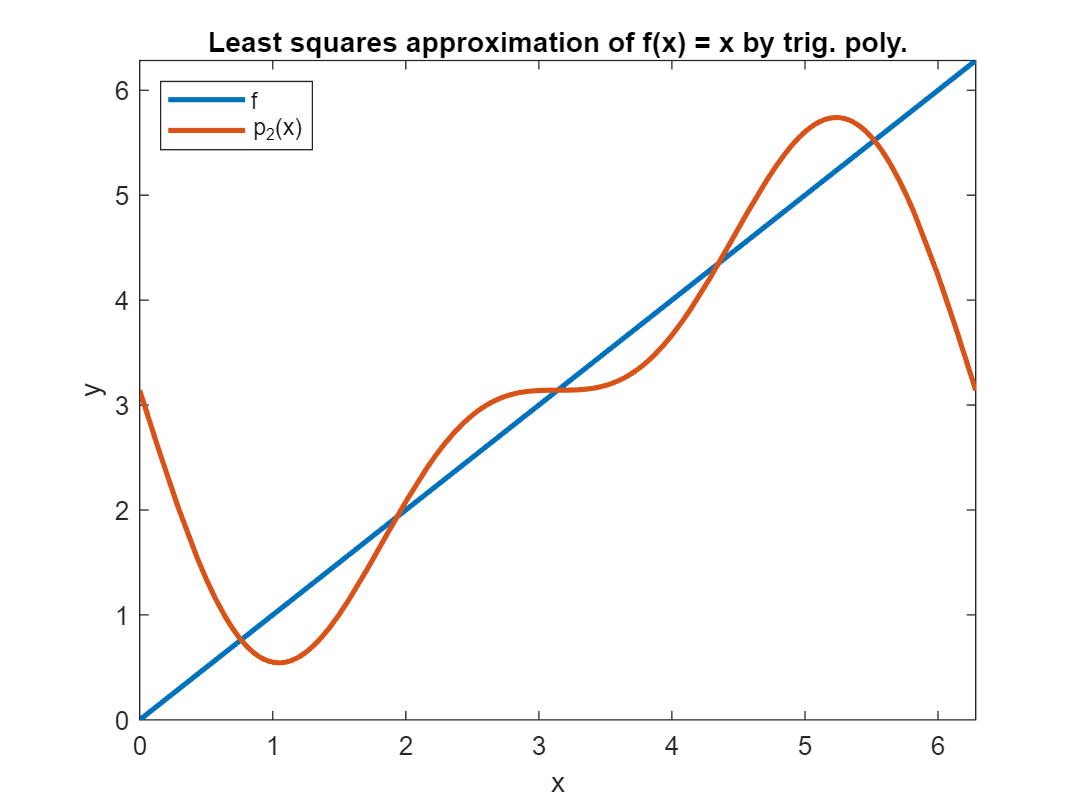

figure
fplot(f, [0,2*pi], 'DisplayName','f', 'LineWidth', 2)
hold on
fplot(Proj_f, [0,2*pi], 'DisplayName','p_2(x)', 'LineWidth', 2)
legend('location', 'northwest')
xlabel('x'), ylabel('y')
title(sprintf('Least squares approximation of f(x) = %s by trig. poly.', char(f)))

It's not much to look at just yet, but suppose we took more terms in our trigonometric polynomial.

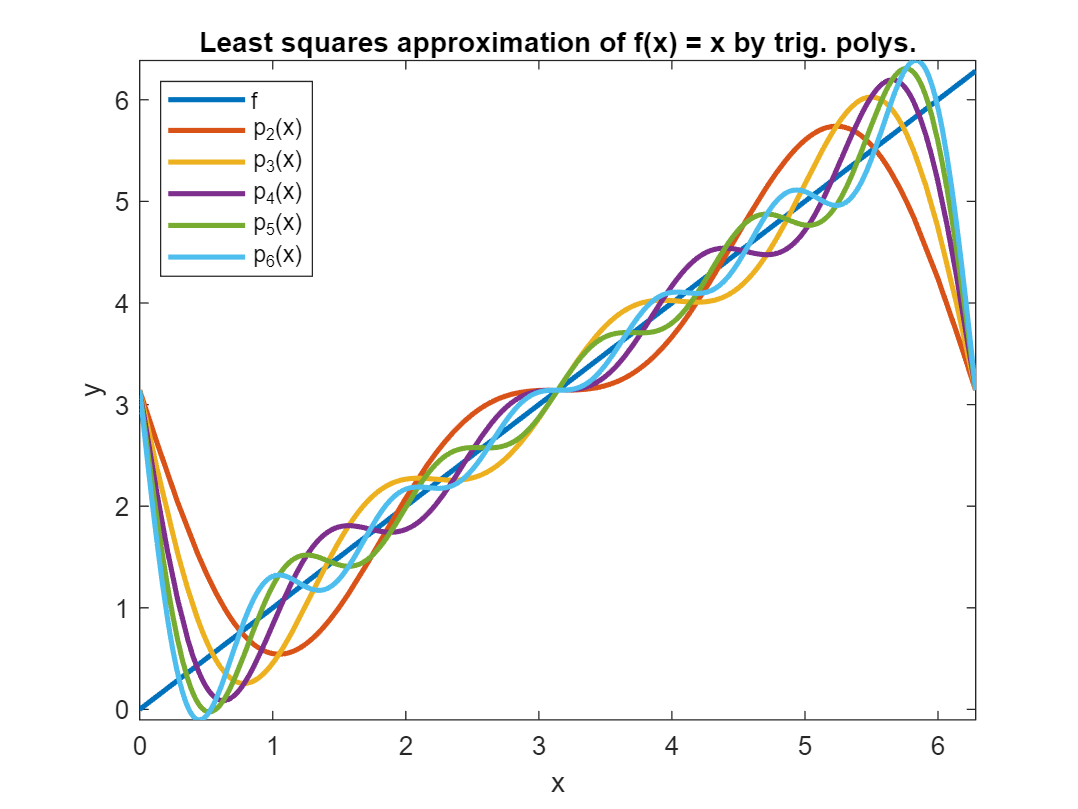

N = 6;
for n = 3:N
    TPbasis = [cos((0:n).*x) sin((1:n).*x)];
    Q = TPbasis ./ nrm(TPbasis);
    fplot(Q * ip(f, Q)', [0,2*pi], 'Displayname', sprintf('p_{%d}(x)', n), 'LineWidth', 2);
end
title(sprintf('Least squares approximation of f(x) = %s by trig. polys.', char(f)))

One might hope that the sequence of approximations $p_n(x)$ for larger and larger value of $n$ would *converge* to $f(x)$.  That is, we could write


$$f(x) = \sum_{k=0}^\infty a_k \cos(kx) + \sum_{k=1}^\infty b_k \sin(kx)\,.$$


The right hand side is known as the *Fourier series* for $f$, and it has many applications in mathematics and the sciences.  Conditions under which convergence can be achieved is left for your studies of partial differential equations, where such series are of the utmost importance.

## **6.5 Summary**

- A **vector space** is any set of objects, along with the operations of addition and scalar multiplication, that satisfy the 10 axioms.

-     A subset of a vector space is itself a vector space, called a **subspace**, provided it is closed under addition and scalar multiplication.

-     The number of vectors in any basis for a vector space is its dimension.

-     Not all vector spaces have bases.  Those that do not are infinite-dimensional.

- A **linear transformation** $T$ maps between vector spaces, and satisfies $T(ku+mv) = kT(u) + mT(v)$.

-     The **kernel** of $T$ is the set of all vectors in $V$ that $T$ maps to zero.  Its dimension is $\textrm{nullity}(T)$.

-     The **range** of $T$ is the set of all vectors in $W$ that are the images under $T$ of at least one vector in $V$.  Its dimension is $\textrm{rank}(T)$.

-     A linear transformation from finite-dimensional vector space $V$ satisfies $\textrm{rank}(T) + \textrm{nullity}(T) = \dim(V)$.

-     A linear transformation can be represented by a matrix $A$, which maps coordinate vectors to coordinate vectors.

-     A linear transformation that is one-to-one and onto is called an **isomorphism**.

-     Every real $n$-dimensional vector space is isomorphic to $\mathbb{R}^n$.

- An **inner product** on a vector space is a function that associates a real number with every pair of vectors in the space, satisfying 4 axioms.

-     An **inner product space** is a vector space equipped with an inner product.

-     An inner product $\langle\cdot,\cdot\rangle$ defines a norm by $\|u\| = \sqrt{\langle u,u\rangle}$.

-     The Gram-Schmidt process generates an orthonormal basis under a given inner product.

-     Functions from infinite-dimensional spaces can be projected onto finite-dimensional subspaces.  This is least squares function approximation.